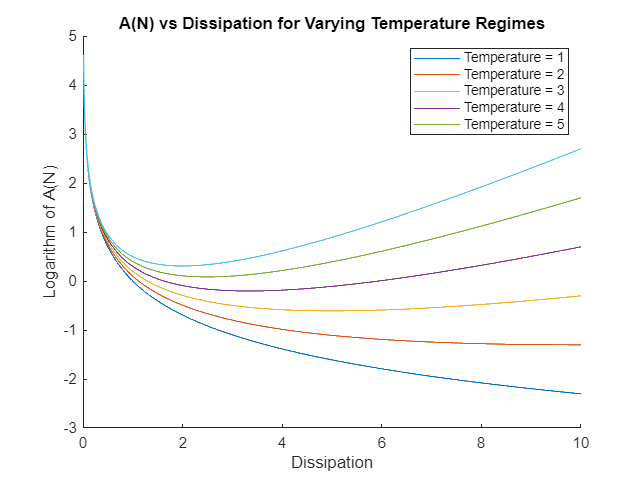

Temperature = 1/2;
Dissipation_Range = 0:0.01:10; 

figure;
hold on;

for Temperature = 0:0.2:1
Step_Sizes = Inverse_Maxwell_Boltzman_Form(Dissipation_Range, Temperature);

plot(Dissipation_Range, log(Step_Sizes))
xlabel('Dissipation');
ylabel('Logarithm of A(N)');
title('A(N) vs Dissipation for Varying Temperature Regimes');
legend;

end

legend(arrayfun(@(x) sprintf('Temperature = %d', x), 1:5, 'UniformOutput', false));
hold off


function Step_Size = Inverse_Maxwell_Boltzman_Form(Dissipation, Temperature)

%------------ Natural Units -----------%
    hbar = 1;
    boltzmanns_constant = 1;
%--------------------------------------%

    Step_Size = (1./Dissipation).* exp(Dissipation ./ 2*(boltzmanns_constant * Temperature));

end

function Step_Size = Maxwell_Boltzman_Form(Dissipation, Temperature, Coefficient)

%------------ Natural Units -----------%
    hbar = 1;
    boltzmanns_constant = 1;
%--------------------------------------%

    Step_Size = (Dissipation.^3 / hbar) .* Coefficient .* exp(-Dissipation ./ (boltzmanns_constant * Temperature));

end

function Step_Size = Poissonian_Form(Dissipation, Coefficient, k)

%------------ Natural Units -----------%
    hbar = 1;
%--------------------------------------%

    Step_Size = (Dissipation.^(k+1)/(factorial(k)*hbar)).*Coefficient.*exp(-Dissipation);

end

function Step_Size = Normal_Form(Dissipation, Coefficient, Mean, Variance)

%------------ Natural Units -----------%
    hbar = 1;
%--------------------------------------%

    Step_Size = (Dissipation./hbar).*Coefficient.*(1/sqrt(2*pi*(Variance^2))).*exp(-((Dissipation-Mean).^2)./Variance);

end